#                        

# **Digital Signal Processing  **

**Special Assignment                                                                       Date :- 20 / 04 / 2024**

**Term Assignment  - 2 **

**(22bec121 Sneh Shah)                                                         (22bec132 Unnat Thakkar)**

**Topic :- Echo Removal using MATLAB**

**Problem Description :- **To remove echo from audio signals using MATLAB to improve audio quality by implementing algorithms such as adaptive filtering or convolution . The goal is to enhance the clarity of the recorded signal by reducing or eliminating echo , with evaluating metrics including SNR improvement and subjective audio quality assessment .

**Algorithm / MATLAB Code :- **

load mtlb % This can be any audio file (.wav) file 
Fs = 8000 ; % Sampling Frequency
%soundsc(mtlb , Fs)

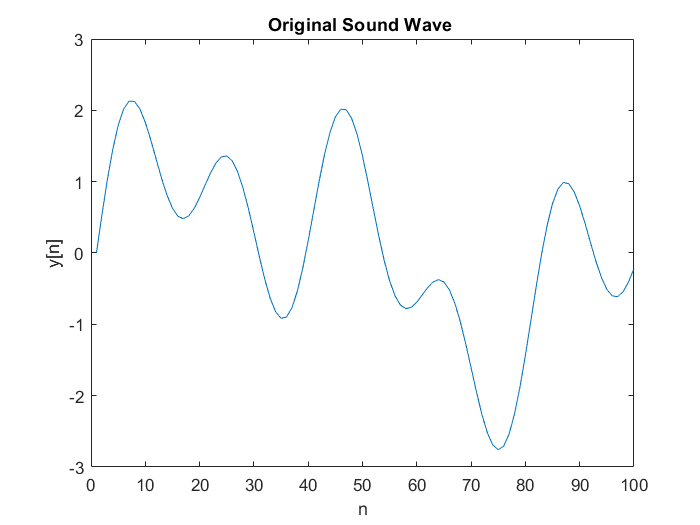

clc ; clear all ; close all ;
Fs = 20000 ;  
N = 100 ;
t = 0 : 1/Fs : (N-1)/Fs ;

y = sin (2 * pi * 200 * t ) + sin (2 * pi * 500 * t) + sin (2 * pi * 1000 * t) ;
plot(y) ; title("Original Sound Wave ") ; ylabel("y[n]") ; xlabel("n") ;

**y(n) = x(n) + αx(n−Δ)**

Here , delta is** Delayed Samples **and alpha is **Attenuation Factor .**

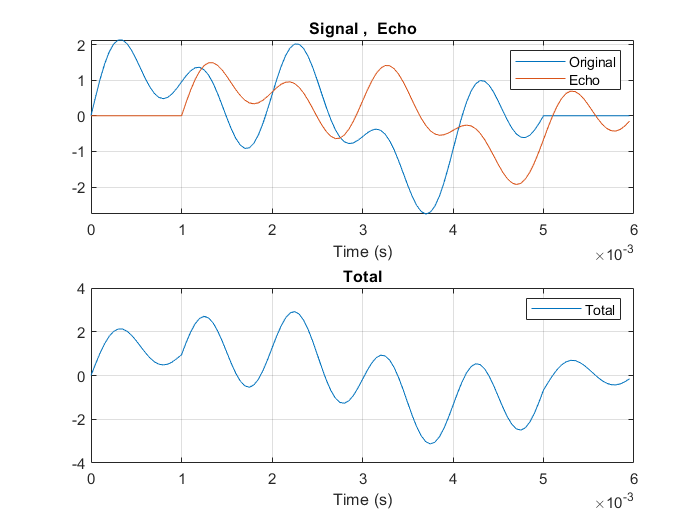

Fs = 20000 ; td = 0.001 ; delta = round(Fs * td) ; alpha = 0.7 ; 

original = [y  zeros(1 , delta) ] ;
echo = [zeros(1 , delta)  y] * alpha ;

len = max(length(original)  , length(echo)) ;

original =[original zeros(1 , len - length(original))] ; echo = [echo zeros(1 , len - length(echo))] ;
Final = original + echo ;

t1 = (0 : len - 1 ) / Fs ;

subplot(2,1,1) ; plot(t1 , [original ; echo]) ;
legend("Original","Echo") ; xlabel("Time (s)") ; title ("Signal ,  Echo") ; grid on ;
subplot(2,1,2) ; plot(t1 , Final) ;
legend("Total") ; xlabel("Time (s)") ; title ("Total") ; grid on ;

From the above chunk of code  , we generated the **Final signal with Echo** . This process includes **Delaying** the Original Signal and **Attenuating** it and then **Adding** it with the Original Signal .

Now , we start to find the** Autocorrelation** using **xcorr() function** and further calculate **Lags **for different samples .

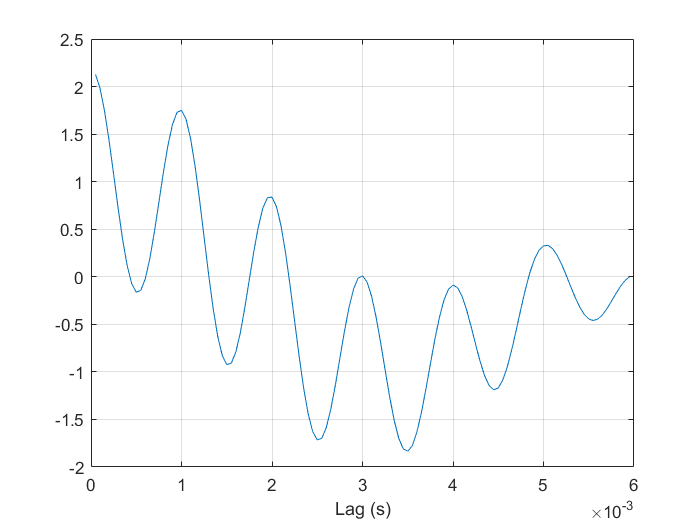

[R,lag] = xcorr(Final , "unbiased") ;

R = R(lag > 0) ;
lag = lag(lag > 0) ;

figure ;
plot(lag/Fs , R) ; xlabel("Lag (s)") ; grid on ; 

Here , from the curve we get the** Idea** that** Peaks are an indication** of **Echo arrival** . 

Now , we find the **Peaks** to remove the Echo that was introduced .Further , we cancel the** Echo** by filtering the Signal by an IIR Filter followed by the equation :-

**w(n) + αw(n−Δ) = y(n).**

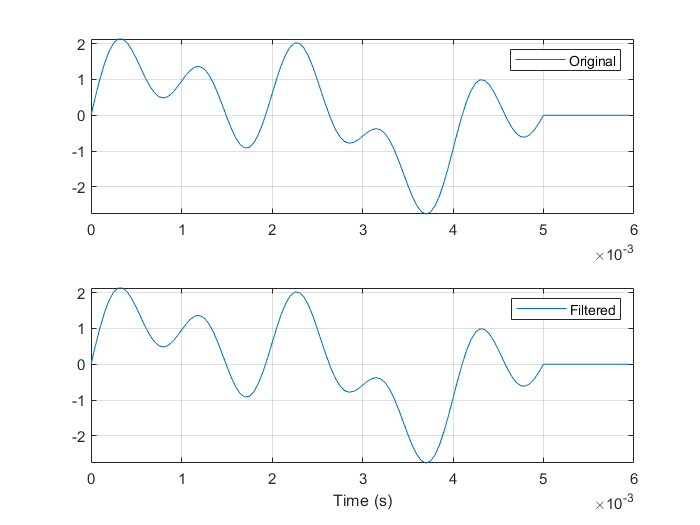

[~ , loc] = findpeaks(R  , lag , 'MinPeakHeight', 0.5) ;
    
Final1 = filter(1 , [1 zeros(1 , loc(1) - 1) alpha] , Final) ;

subplot(2,1,1) ; plot(t1 , original) ; legend("Original") ; grid on ;

subplot(2,1,2) ; plot(t1 , Final1) ; legend("Filtered") ; xlabel("Time (s)") ; grid on ;

Finally , we **removed the Echo** that was generated earlier . Similarly we can use the above algorithm to remove Echo in **Real Life Scenarios** .

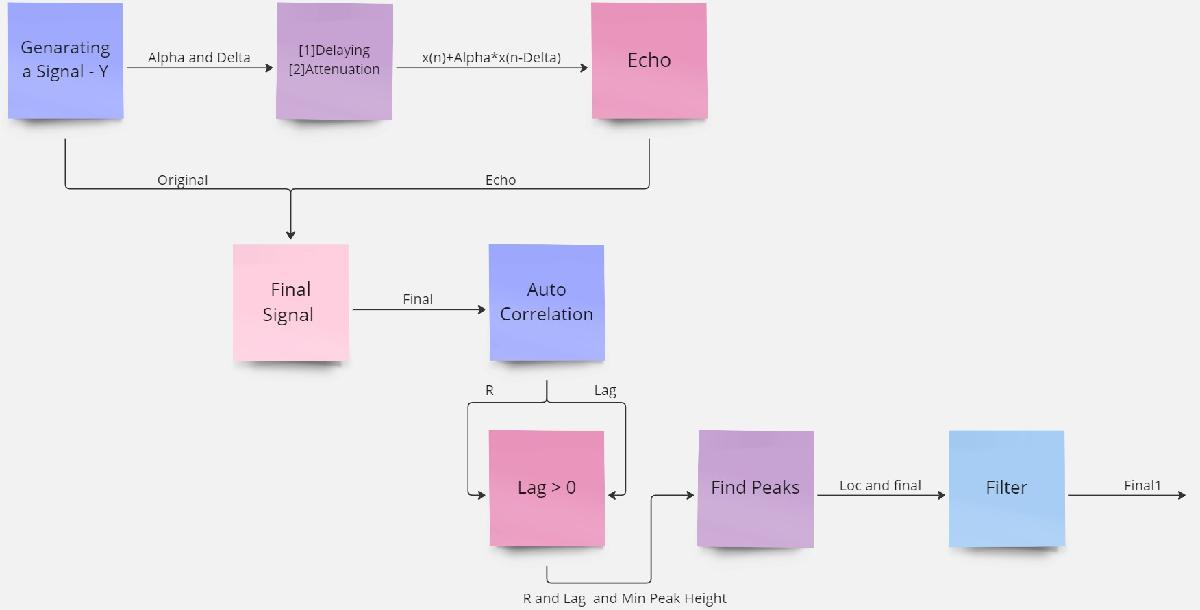

**Observations :-  **1) We can clearly see that **echo signal was noticeable** in the signal .

                            2) Filtering effective **suppressed echo components** .

                            3) From this experiment , we learnt how to cancel echo components from the original signal and apply the** same algorithm for any recorded signal .**

**Conclusion :-**  This experiment successfully demonstrated the **need for Echo Removal **, and sets the stage for **Adaptive Echo Removal Algorithms** . We can also further refine our results for a recorded signal as well and further **increase efficiency** with Adaptive Echo Filtering .